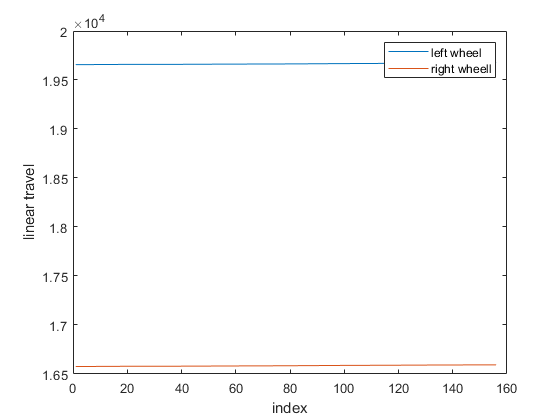

% 36.5
% Loading in dataset
load("bod_encoders.mat")
% assigning values from dataset
t = dataset(:,1);
LT_L = dataset(:,2);
LT_R = dataset(:, 3);
% plotting linear travel 
cla
figure(1)
plot(LT_L)
hold on 
plot(LT_R)
xlabel('index')
ylabel('linear travel')
legend('left wheel', 'right wheell')
hold off

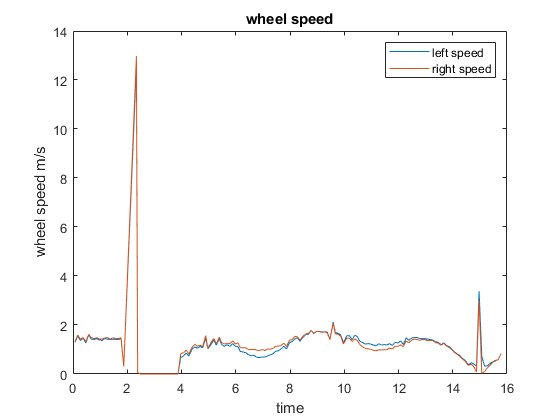

% calculating some derivatives of linear travel to obtain left and right
% wheel velocities

dt = diff(t);
dL = diff(LT_L);
dR = diff(LT_R);
vL = dL./dt;
vR = dR./dt;
cla
% plotting left and right wheel speeds
plot(t(1:end-1), vL)
hold on 
plot(t(1:end-1), vR)
xlabel('time')
ylabel('wheel speed m/s')
legend('left speed', 'right speed')
title('wheel speed')

% determining linear speed & angular velocity using differential drive
% equations

d=.235

d = 0.2350

V = (vL + vR)/2

V =     1.3081
    1.5710
    1.3937
    1.4799
    1.2933
    1.6130
    1.4500
    1.4310
    1.4549
    1.4170


omega = (vL-vR)/d

omega =    -0.1525
   -0.1807
   -0.2421
   -0.0857
   -0.2246
   -0.0934
   -0.2519
   -0.1646
   -0.1696
   -0.1630


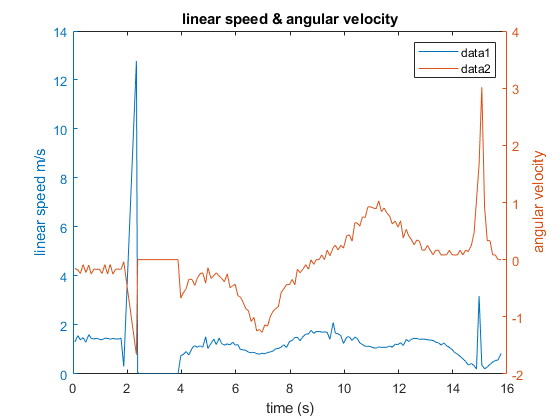

% plotting linear speed & angular velocity
cla
yyaxis left
plot(t(1:end-1), V)
xlabel('time (s)')
ylabel('linear speed m/s')

yyaxis right 
plot(t(1:end-1), omega)
ylabel('angular velocity')
title('linear speed & angular velocity')

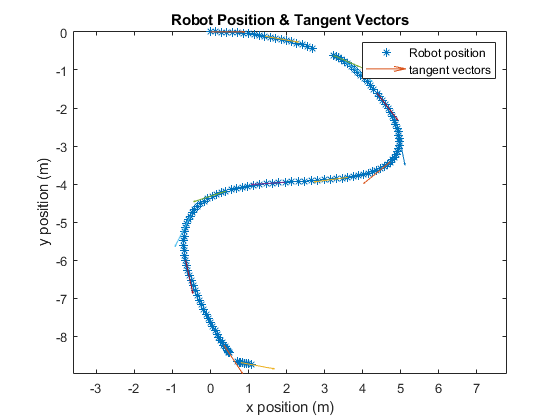

% reconstruct path and angle of robot over course of t, using linear and
% angular velocities derived from differential drive equations & wheel
% velocities. 


path = zeros(length(t), 2);
theta = zeros(length(t), 1);

for n=1:length(dt)
    path(n+1,1) = path(n,1)+V(n)*cos(theta(n))*dt(n); 
    path(n+1, 2) = path(n,2)+V(n)*sin(theta(n))*dt(n);
    theta(n+1) = theta(n)+omega(n)*dt(n);
end

cla reset 
% plotting the x and y values of the path against each other 

plot(path(:,1), path(:,2), '*')
hold on 
% plotting tangent vectors every 10 time stamps
for k=1:10:length(path)
    quiver(path(k,1), path(k,2), cos(theta(k)), sin(theta(k)))
end
axis equal;
legend('Robot position', 'tangent vectors')
xlabel('x position (m)')
ylabel('y position (m)')
title('Robot Position & Tangent Vectors')

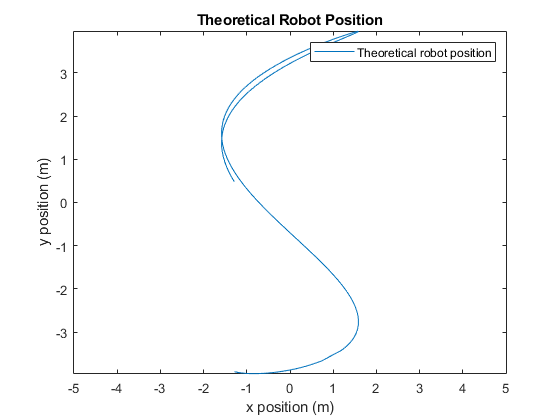

% setting up math to plot theoretical graph

syms time
B = .3;
% d= .235;
% this is the equation of the bridge
ri=4*.3960*cos(2.65*(B*time+1.4));
rj=4*(-.99)*sin(B*time+1.4);
rk=0*B*time;
r=[ri,rj,rk];

% setting numerical values for entire path 
for n=1:length(t)
    r_num(n,:)=double(subs(r,time,t(n)));
end
cla reset
% plotting path x and y values
plot(r_num(:,1), r_num(:,2))
axis equal;
legend('Theoretical robot position')
xlabel('x position (m)')
ylabel('y position (m)')
title('Theoretical Robot Position')

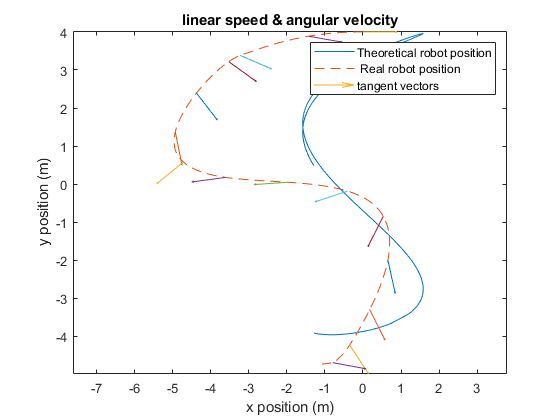

% overlaying real onto theoretical path created above

% plotting theoretical
cla reset 
plot(r_num(:,1), r_num(:,2))
hold on 
% plotting real path
plot(-(path(:,1)), path(:,2)+4, '--')
hold on 

% plotting tanget points (broken because of adjustments to Neato's real
% path)
for k=1:10:length(path)
    quiver(-path(k,1), path(k,2)+4, cos(theta(k)), sin(theta(k)))
end
% setting up plot, legends, etc.
axis equal
legend('Theoretical robot position',' Real robot position', 'tangent vectors')
xlabel('x position (m)')
ylabel('y position (m)')
title('linear speed & angular velocity')

hold off